# Figure 3A

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);

dataDir = '..\..\FINAL DATA files';
load([dataDir filesep 'A062_data.mat'],'S','settings','allIF');
conditions = settings.conditions

framesPerHr = 60/12;
frameDrugAdded = 13;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,1)),1);
    apcGateAll = false(length(dat.POI(:,1)),1);
    cdkHighGate = false(length(dat.POI(:,1)),1);
crlGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
        if dat.POI(n,1) + round(20*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)) < .02;
            apcGateAll(n) = ~isnan(dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)));
        end
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) > .7;
        end
        if dat.POI(n,1) > 1 * framesPerHr
            crlGate(n) = dat.crlNuc(n,dat.POI(n,1) - 1 * framesPerHr) >  100;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
    S(i).apcGate = apcGate;
    S(i).apcGateAll = apcGateAll;

   S(i).crlGate = crlGate;
        S(i).cdkHighGate = cdkHighGate;

end

**Gate cells**

xthresh =1.1e6; %x value of peak
xrange = linspace(2.4e6,1000); %row vector of 1000 points between x and y (all the data)
for i = 1:length(allIF)
    xdata = allIF(i).DNA;
    [f, xi] = ksdensity(xdata,xrange); %probility density plot of values from all xdata to xrange - max x of first peak
    xi_trunc = xi(xi<xthresh); %xi_trunc = all xdata <x thresh (peak of first peak)
    f_trunc = f(xi<xthresh); % f_trunc = probability density estimate for all xdata <x tresh
    [~, maxi] = max(f_trunc); %maxi = index of peak
    N_peak = xi_trunc(maxi); %peak is max of (all xdata<x thresh) which is at index maxi
    S(i).DNA_peak = N_peak;
end


3A left

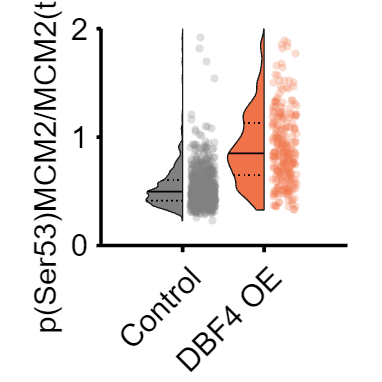

ans = 775

ans = 272

p = 2.3136e-39

conds=[7 1] ;
poi_list = [1];
offset=0;
ally = [];
groups = [];
colors = [.5 .5 .5;.941 .447 .282;.4 .1 .5; 0 .7 1;.1 .4 1;];
  f1= figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
   hold on
gateVals = {{},{},{},{},{},{},{},{}};
rangeVals = {{[]},{[]},{[]},{[]},{[]},{[]},{[]},{[]}};
name = {'mitosis'};
edges = (0:(4/framesPerHr):24);
lims = {[0 6],[0 10],[0 6]};
for p = 1:length(poi_list)
    poiAligned=poi_list(p);
   
   
    
    for i=1:length(conds)
        
        ind= ~isnan(S(conds(i)).POI_time(:,poiAligned)) ;
           sum(ind);
        xdata = S(conds(i)).POI_time(ind,poiAligned);
        ydata = [];
        plot_ydata=[];
        ydata(:, 1) = (S(conds(i)).iRFP1(ind));
        ydata(:, 2) = (S(conds(i)).RFP1(ind));
        ydata(:, 3) = (S(conds(i)).YFP1(ind));
        ydata(:,4) = ydata(:,1)./ydata(:,3);

        ind = xdata > 0 & xdata <4 & ~isnan(ydata(ind,4));

         sum(ind)
              plot_ydata = ydata(ind,4);

    ally = [ally;  plot_ydata];
    groups = [groups; repmat(i,size( plot_ydata))];
 

    end




       cols = repmat({colors(1,:),colors(2,:)}',1,1);
groupcol = repmat([colors([1 2 ],:)],1,1);
figure(f1)
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',.5)
set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.25);

        ylabel('p(Ser53)MCM2/MCM2(total)');
      
        set(gca,'linewidth',2,'fontsize',17)
      xticklabels({'Control','DBF4 OE'})

 ylim([0 2])
 xtickangle(45)
set(gca,'fontsize',17)

% print_pdf(['fig_3Ai.pdf'])

p=mediantest(ally(groups==1),ally(groups==2))

end

3A right

conds=[7 1];
colors = [.5 .5 .5 ;.941 .447 .282;1 .831 0;.333 .302 .541; 1 .831 0;  .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
POI_align = 3;
ally = [];
groups = [];
timeGate = [0 10];

for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,POI_align)) &  ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) & data.apcExpressGate & data.goodCdk;
sum(inds)
    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,1));
   
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 

end

ans = 1392

ans = 796

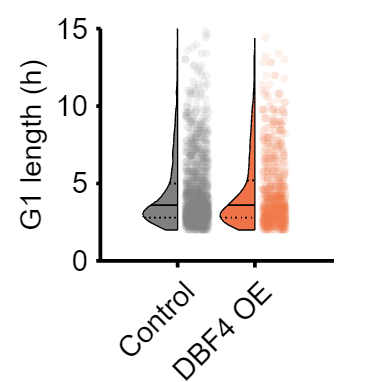


figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',1,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'G1 length (h)'])


xticklabels({'Control','DBF4 OE'})
ylim([0 15])
 xtickangle(45)
set(gca,'fontsize',16,'linewidth',2)
axis square

  p=mediantest(ally(groups==1),ally(groups==2))

p = 0.9088



 % print_pdf(['fig_3Aii.pdf'])